# Actividad 1.1 (Mapeo de coordenadas)

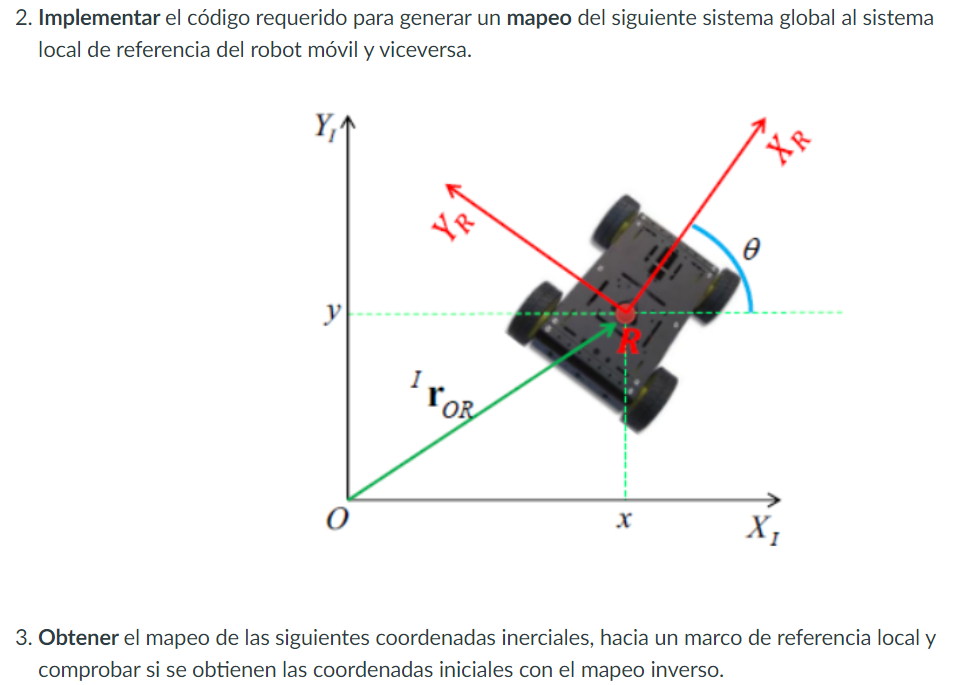

%Limpieza de pantalla
clear all
close all
clc

tic
%Declaracion de variables simbolicas
syms x(t) y(t) th(t) t %Grados de libertad del robot movil

%Creamos el vector de posicion
xi_inercial = [x; y; th];
disp('Coordenadas generalizadas');

Coordenadas generalizadas


pretty (xi_inercial);

/  x(t) \
|       |
|  y(t) |
|       |
\ th(t) /




%Creamos el vector de velocidades a partir de la derivada del vector de
%posicion con respecto al tiempo
xip_inercial = diff(xi_inercial, t);
disp('Velocidades generalizadas')

Velocidades generalizadas


pretty(xip_inercial);

/   d      \
|  -- x(t) |
|  dt      |
|          |
|   d      |
|  -- y(t) |
|  dt      |
|          |
|  d       |
| -- th(t) |
\ dt       /




%defino mi vector de posicion y mi matriz de rotacion
%Vector de posicion
P(:,:,1) = [x;y;th]; %Viene siendo xi_inercial
%Matriz de rotacion alrededor del eje z...
R(:,:,1) = [cos(th) -sin(th)    0;
            sin(th) cos(th)     0;
            0       0           1];

%Realizo mi transformacion del marco de referencial global al local...
xi_local = R(:,:,1)*P(:,:,1)

$$xi\_local = \left(\begin{array}{c} \cos\left(\mathrm{th}\left(t\right)\right)\,x\left(t\right)-\sin\left(\mathrm{th}\left(t\right)\right)\,y\left(t\right)\\ \cos\left(\mathrm{th}\left(t\right)\right)\,y\left(t\right)+\sin\left(\mathrm{th}\left(t\right)\right)\,x\left(t\right)\\ \mathrm{th}\left(t\right) \end{array}\right)$$


%Defino coordenadas inerciales para un tiempo 1
x1=1; %Posicion inicial eje x
y1=1; %Posicion inicial eje y
th1=45; %Orientacion inicial del robot

%Defino mi vector de posicion y matriz de rotacion para un timepo 1
Pos_1=[x1; y1; th1];
Rot_1  =   [cos(th1) -sin(th1)    0;
            sin(th1) cos(th1)     0;
            0        0            1];

%Realizo mi transformacion del marco de referencial inercial al local...
xi_local_1 = Rot_1*Pos_1

xi_local_1 =    -0.3256
    1.3762
   45.0000



%Obtengo la magnitud del vector resultante
magnitud= sqrt(xi_local_1(1)^2 + xi_local_1(2)^2)

magnitud = 1.4142


%Compruebo que me duvuelva el vector inercial
inv_Rot_1 = inv(Rot_1);
xi_inercial_1 = inv_Rot_1*xi_local_1

xi_inercial_1 =      1
     1
    45


Primero se crean las variables simbolicas, luego se crea el vector de posición a partir de las coordenadas (x,y) y del ángulo de rotación (theta), y el vector de velocidades se crea con la derivada del vector de posición. Después se define el vector de posición y la matriz de rotación alrededor del eje z. Luego se definen las coordenadas inerciales del robot movil y se define el vector de posición y matriz de rotación con los valores de las coordenadas y se realiza la transformación del marco de referencia inercial al local con las coordenadas multilpicando la matriz de rotación por el vector de posición. Después se obtiene la magnitud por medio del teorema de pitagoras con las coordenadas locales x,y del robot, para obtener la distancia hacia el centro del robot movil. Por último se hace la comprobación calculando la inversa de la rotación por la transformación del marco de referencia inercial al local   

Inciso a)               inciso b)            inciso c)            inciso d)            

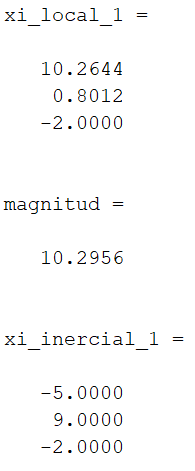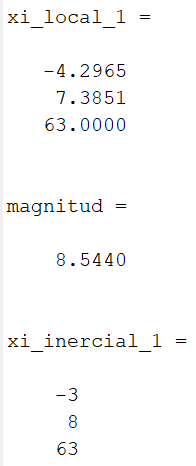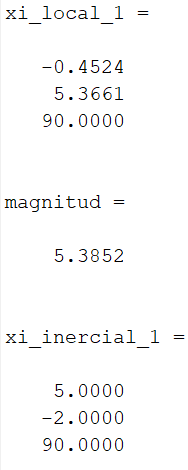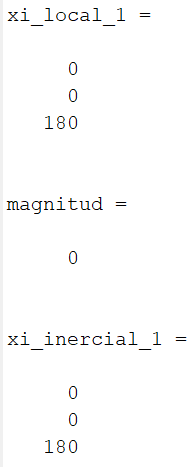

inciso e)                inciso f)            inciso g                inciso h)

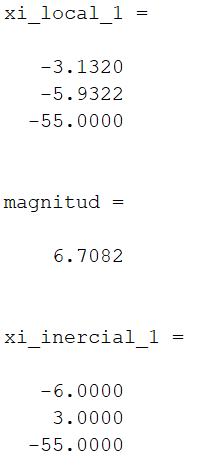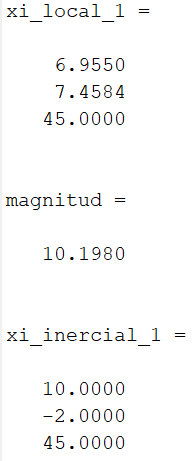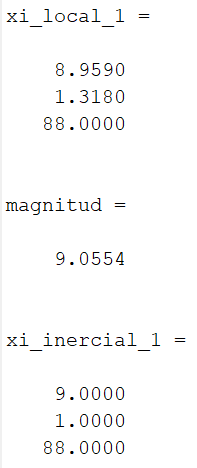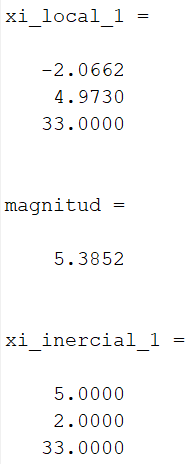

inciso i)                inciso j)                inciso k)                inciso l)

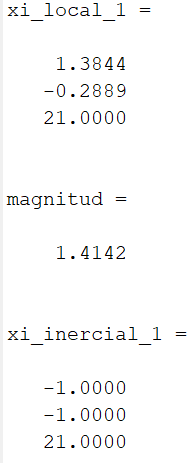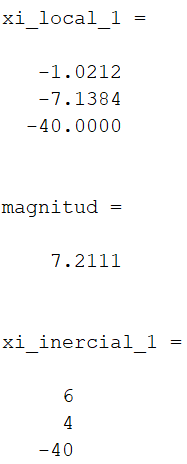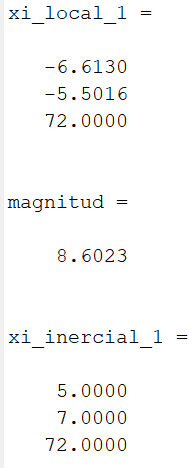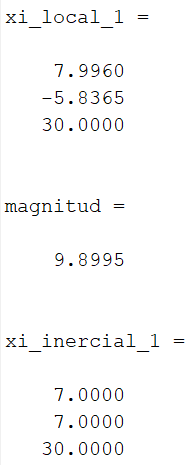

inciso m)            inciso n)                inciso ñ)                inciso o)

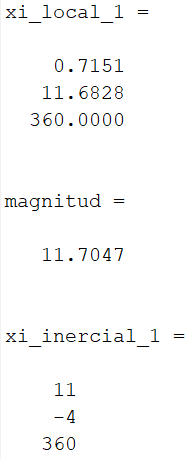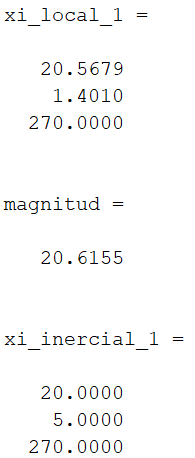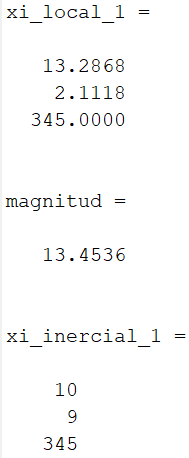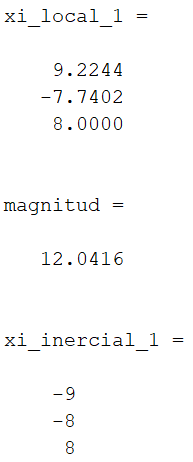

inciso p)            inciso q)                 inciso r)                inciso s)